% Лабораторная работа №2
% Кирилло Дмитрий, 2 курс, 5 группа ММФ БГУ

clear;
clc
% =============================
% Задание 2.6
% =============================
2/(sqrt(2) + sqrt(2)*j);
((2+3i)/(4-i)) + ((2-3i)/(1+4i));
sin(1+(1-i)^(1/3));

% =============================
% Задание 2.8
% =============================
exp(1+2i);
(1+2i).^(exp(1));
(1+2i).^(1+2i);

% =============================
% Задание 2.10
% =============================
b = (1:4);
c = b';

% =============================
% Задание 2.11
% =============================
x = [1+2i 2-i 3 4];
y = x';
z = x.';
X = x;

% =============================
% Задание 2.13
% =============================
A = [1:3; 4:6; 7:9; 10:12];
A(3,:);
A(:, 2) = [];
A = A(:,[end,1]);
A = A([end:-1:1],:);
A = [1:3; 4:6; 7:9; 10:12];
a = A(2,3);
a = A(10);

% =============================
% Задание 2.14
% =============================
zeros(4,4);
eye(4,4);
rand(4,4);
randn(4,4);

% =============================
% Задание 2.19
% =============================
A = [1:3; 4:6;7:9];
b = A(3,:);
b = A(:,2);
b = A(1:3,2);
B = A(1:3, 2:3);
B = A([1 3], :);
B = A([3 2 1], :);
B = A(:,[3:-1:1]);
A(:);
p = [3 1 2];
n = [2 3 1];
A(p, :);
A(n,:);
A(:,p);
A(:,n);
A(p,p);
A(n,n);

% =============================
% Задание 2.20
% =============================
A = [1;2;3;4;5;6];
B = A';
C = A.';
D = -A;
B = A + 2*D;
C = A' * A;
a = [1:4];
E = a'*a;
f = a* a';
d = A/2;
%G = A^2
B = A.^2;
C = A.*A;
b = diag(A);

% =============================
% Задание 2.21
% =============================
A = magic(5);
A(2,:);
A(:,4);
A(end, :);
A([1, 5]);
A(1,5 :-2: 1);
A(5:-1:1,5:-1:1);
A(1:2:end);
A(:);
A(:,end);

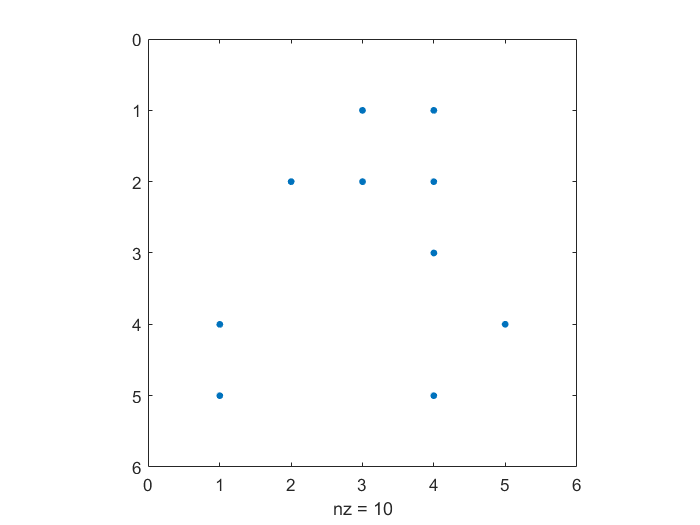

% =============================
% Задание 2.25
% =============================
A = randn(5,5);
B = randn(5,5);
A>B;
A==B;
A~=B;
A<=B;
spy(A>0);

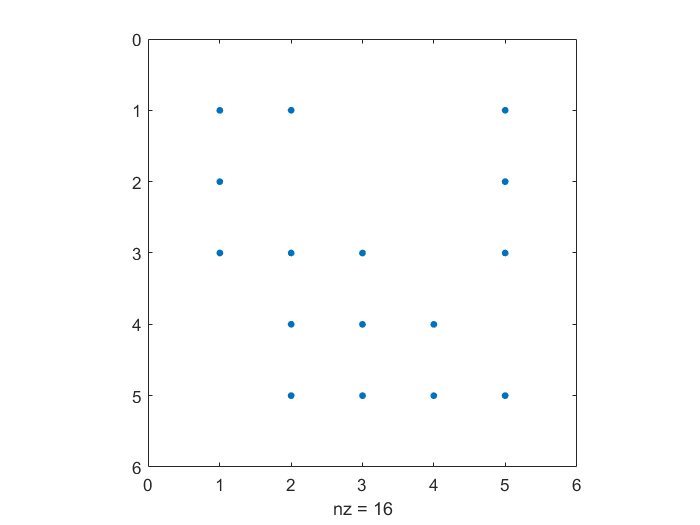

spy(A<.1);

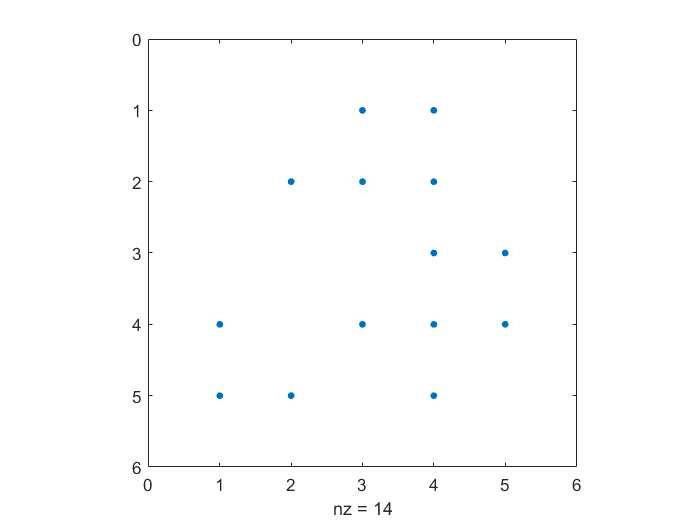

spy(A>=B);

% =============================
% Задание 2.26
% 1 строка
% =============================
A = rand(2,3);
B = rand(3,3);
v = rand(3,1);
w = rand(2,1);
%A+B;
A+A;
%v+w;
%v-w

% =============================
% Задание 2.26
% 2 строка
% =============================
A*B;
%B.*A; dimensions not equal 
%A'.*B; dimensions not equal 
B*A';
%A*A; we should using .* 
A'*A;
A*A';
B*B;

% =============================
% Задание 2.26
% 3 строка
% =============================
A*v;
%v*A; dimensions not equal
%A'*v; we should using .*
%w*A'; dimensions not equal
v*v';
v'*v;
B*v;
%B*w dimensions not equal

% =============================
% Задание 2.33
% =============================
A = rand(5,6);
B = rand(3,2);
S = A([2:4],[3:6]);
A([2:4],[4 5]) = B;
D = zeros(11,11);
D([1:5],[1:6]) = A;
D([6:11],[7:11]) = A';

% =============================
% Задание 2.34
% =============================
A = randi(5,5);
B = A([1:3],[1:3]);
S = A([3:5],[3 4]);
D = A([1 2],[1:3]);
E = A([4 5],[4 5]);


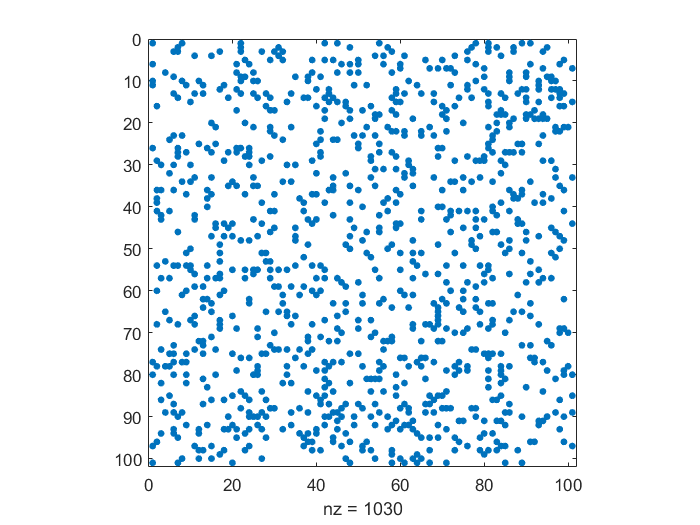


% =============================
% Задание 2.36
% =============================
M = 101;
X = rand(M)<.1;
spy(X);

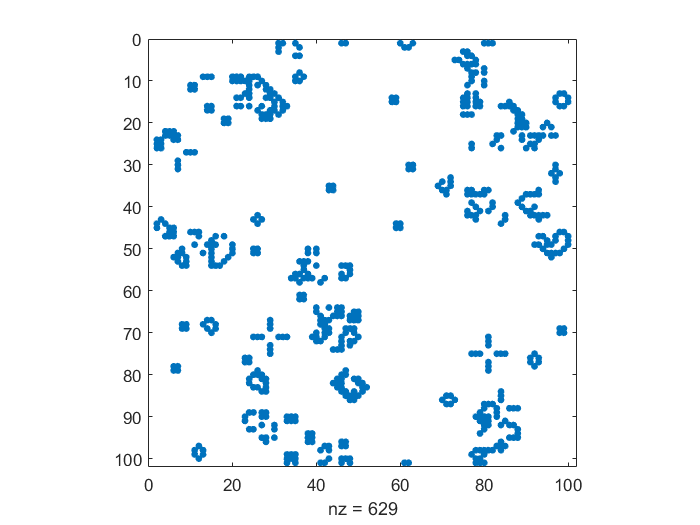

n =[M 1:M-1];
p = [2:M 1];
for k=1:100
   N = X(n,:) + X(p, :) + X(:,n) + X(:,p)+ X(n,n)+ X(p,p)+...
    +X(n,p)+ X(p,n);
    X = (X&(N==2))|(N==3);
    spy(X);
    drawnow;
end